xyz_camera_calibration.mlx

Alex Elias

Uses UWB distance readings to calculate XYZ of camera/UWB calibration checkerboard

## Read in UWB readings from ROS

%bag = rosbag('2021-09-13-11-30-10.bag')
bag = rosbag('2021-09-15-12-02-22.bag')

bag =   BagSelection with properties:

           FilePath: 'E:\Alex\Dropbox\Dropbox\RPI\PhD\Swarm Robotics\ARM-20-02-C-15-Swarm-Robotics\matlab_scripts\2021-09-15-12-02-22.bag'
          StartTime: 1.6317e+09
            EndTime: 1.6317e+09
        NumMessages: 15051
    AvailableTopics: [3×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [15051×4 table]


bag.AvailableTopics

ans = 3×3 table
                     NumMessages       MessageType                                                                                                  MessageDefinition                                                                                            
                     ___________    _________________    ________________________________________________________________________________________________________________________________________________________________________________________________________

    /rosout                4        rosgraph_msgs/Log    {'int8 INFO↵int8 WARN↵int8 ERROR↵int8 FATAL↵std_msgs/Header Header↵  uint32 Seq↵  Time Stamp↵  char FrameId↵int8 Level↵char Name↵char Msg↵char File↵char Function↵uint32 Line↵char[] Topics↵'}
    /uwb_serial_x       7523        std_msgs/String      {0×0 char                 


bSel_x = select(bag,'Topic','/uwb_serial_x');
msgs_x = readMessages(bSel_x);
t_x = bSel_x.MessageList.Time;

bSel_y = select(bag,'Topic','/uwb_serial_y');
msgs_y = readMessages(bSel_y);
t_y = bSel_y.MessageList.Time;

## Parse readings, find average distances and statistics

[anchor_names, anchor_locs] = anchor_info(msgs_x)

anchor_names = 4×1 string array
    "29EF"
    "2A32"
    "2ED1"
    "0D40"


anchor_locs =    10.7600   10.9700    2.7600         0
    4.2400         0    4.3200         0
    3.1400    3.2500    3.2900    3.5700


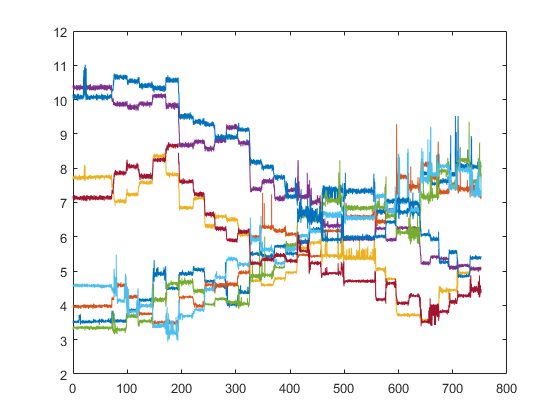

dist_mat_x = get_distances(msgs_x, anchor_names);
dist_mat_y = get_distances(msgs_y, anchor_names);

t_0 = min([t_x; t_y]);
t_x_offset = t_x-t_0;
t_y_offset = t_y-t_0;

plot(t_x_offset, dist_mat_x); hold on
plot(t_y_offset, dist_mat_y); hold off


% t_start = [5  86 126 208 230 263 284 310 401 430 453 470 491 517 538 565 581 612 642 674 698 718 742 765 785] 
% t_end =   [57 95 140 220 250 272 294 343 418 445 460 479 500 525 554 577 594 619 665 688 707 730 750 772 800]
t_start = [26 83 104 124 151 175 198 225 244 263 286 311 332 355 374 396 422 440 470 507 566 582 602 623 647 664 677 698 715 737]

t_start =     26    83   104   124   151   175   198   225   244   263   286   311   332   355   374   396   422   440   470   507   566   582   602   623   647   664   677   698   715   737


t_end   = [68 93 116 143 166 192 217 240 259 279 300 320 342 364 388 408 431 454 486 551 573 592 615 634 653 669 690 704 726 743] 

t_end =     68    93   116   143   166   192   217   240   259   279   300   320   342   364   388   408   431   454   486   551   573   592   615   634   653   669   690   704   726   743


N_pts = length(t_start)

N_pts = 30


avg_dist_mat_x = nan(4, N_pts);
avg_dist_mat_y = nan(4, N_pts);
std_mat_x = nan(4, N_pts);
std_mat_y = nan(4, N_pts);

for i = 1:N_pts
    ind_x =  t_x_offset >= t_start(i) & t_x_offset <= t_end(i);
    ind_y =  t_y_offset >= t_start(i) & t_y_offset <= t_end(i);
    
    t_x_i = t_x_offset(ind_x);
    dist_mat_x_i = dist_mat_x(ind_x, :);
    t_y_i = t_y_offset(ind_y);
    dist_mat_y_i = dist_mat_y(ind_y, :);
    
    
%     figure; plot(t_x_i, dist_mat_x_i)
%     figure; plot(t_y_i, dist_mat_y_i)
    
    avg_dists_x = mean(dist_mat_x_i,'omitnan');
    std_x = std(dist_mat_x_i,'omitnan')*1e3;
    
    avg_dists_y = mean(dist_mat_y_i,'omitnan');
    std_y = std(dist_mat_y_i,'omitnan')*1e3;
    
    avg_dist_mat_x(:, i) = avg_dists_x;
    avg_dist_mat_y(:, i) = avg_dists_y;
    
    std_mat_x(:,i) = std_x;
    std_mat_y(:,i) = std_y;
end

avg_dist_mat_x

avg_dist_mat_x =     3.5359    3.5437    3.8652    4.1546    4.9197    4.5007    4.9253    5.0396    4.6997    4.5516    4.0209    4.3761    5.5011    5.4231    5.7226    5.5108    5.8564    6.2113    7.3609    7.3366    6.7297    7.0423    6.7204    6.7642    7.8442    7.5500    7.6150    7.8232    8.0588    8.0415
    3.9768    4.5850    4.2458    3.7580    3.4964    3.4921    4.2372    3.9902    4.6015    4.5884    4.6179    4.9554    5.9856    6.2763    6.1676    6.0763    5.4724    5.4369    6.1702    6.5848    6.4506    6.7922    7.7463    7.4554    8.1005    7.7410    7.2980    7.5034    7.3949    7.4019
    7.7408    7.0425    7.2304    7.5768    8.3565    7.8159    6.8434    7.1274    6.3174    6.5913    6.5004    6.0647    4.7246    4.5979    4.7840    4.9589    5.6674    5.8298    5.4459    5.3975    5.0507    4.7691    3.7221    3.7230    3.5753    3.9241    4.4287    4.4488    4.9482    5.0603
   10.3525    9.8625    9.7768    9.8763   10.1091    9.8233    8.6746    8.7778

avg_dist_mat_y

avg_dist_mat_y =     3.3479    3.2946    3.6883    3.5380    4.1713    4.6286    4.6682    4.4247    4.0293    4.1905    4.0932    4.0496    4.8518    4.8877    5.1081    5.7499    6.6267    6.4814    7.0601    6.8405    6.8649    6.6206    6.1251    6.0811    7.1547    7.1816    7.9063    7.4823    8.2385    7.6158
    4.5705    4.1381    3.8237    3.9945    3.4088    3.2034    3.6993    3.8758    4.4712    4.8239    5.3544    5.1960    5.9181    5.6266    5.2314    5.6389    6.0307    6.1603    6.6387    6.5475    7.1941    6.7624    7.0133    6.7886    7.6737    7.8164    8.0643    7.4370    7.9474    7.2482
    7.1371    7.8602    8.0454    7.7618    8.2488    8.6559    7.6017    7.2356    6.6616    6.2390    5.9019    6.1453    5.2266    5.3434    5.4609    5.3008    5.5807    5.2283    4.9384    4.7086    4.1700    4.6485    4.0695    4.2845    3.5248    3.8758    3.8255    4.0945    4.2819    4.4680
   10.0688   10.6586   10.5390   10.4063   10.3297   10.5668    9.5067    9.3521

std_mat_x

std_mat_x =    27.4191   24.9709   14.3769   22.4422   46.1892   24.4253   30.7272   25.6952   22.5837   19.3786   23.5511   25.7884   22.0535   19.4095   21.8472   23.7339   36.4217   29.3365   85.4643   39.4668   37.6086   33.9594   36.6104   98.1523   30.4370   22.0389   38.6718   34.9572   38.8772   32.2503
   25.4412   28.7990   26.1753   20.5059   21.3742   29.1318   20.3235   35.3452   31.6946   33.8986   28.8508   21.9377   31.9191   25.5121   30.2545   25.3458   19.5058   15.8267   19.6341   27.6216   26.8050   30.2040   37.0656   47.9999   37.4811   42.8294   33.9493   42.3292   29.5840   66.9914
   26.6004   27.1182   25.3843   26.5806   27.7570   28.4199   25.9062   25.1019   32.6049   25.7162   32.4177   21.5782   20.7666   17.8945   19.2388   18.5525   26.2469   23.6051   23.9782   68.9931   23.5490   19.1178   19.6323   18.6001   18.5460   28.7169   32.2195   15.7407   19.8703   24.6329
   38.7152   36.1360   39.9532   33.4998   33.3358   40.2474   34.6810   30.9063   30

std_mat_y

std_mat_y =    23.7932   19.8693   31.0506   25.0782   34.4387   36.3340   37.6566   30.2716   15.0716   22.5803   29.4376   23.5927   35.3803   20.8284   15.5049   32.2411   33.7539   33.0934   35.5106   33.3441   25.9734   46.8356   32.9326  107.0141   34.9559   30.4631   41.0805   41.8377   31.3075   33.0532
   24.5640   27.0931   20.7855   28.8502   35.8393  103.9224   29.5183   22.9894   27.2031   33.7417   28.8202   24.6668   31.9310   28.2509   30.2454   36.5944   27.6739   27.9477   42.6298   32.9533   34.1137   41.1727  101.6209   30.3338   46.5402   35.7291   29.4705   35.7629   30.9091   62.7206
   31.8798   30.5829   28.3702   36.7499   28.0182   34.4429   30.4001   33.7277   30.2929   29.0564   29.5748   30.3611   25.0372   25.3586   29.5839   23.7842   16.9467   26.5011   19.2543   21.2617   20.4364   20.4186   23.0255   22.1602   20.0416  157.0141   23.0475   30.3329   20.6594   47.7919
   36.0215   32.2304   33.6167   38.4915   40.0239   35.1590   42.9373   39.9201   33

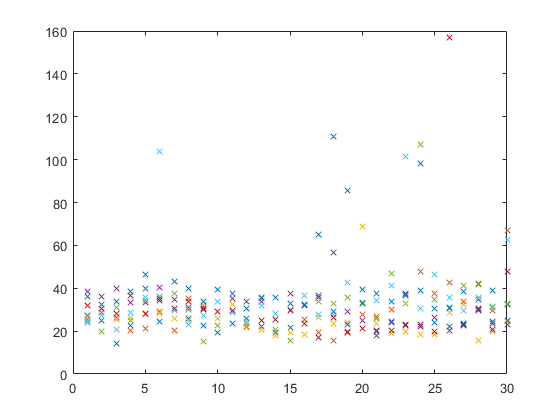

plot([std_mat_x;std_mat_y]','x')

## Localize checkerboard

cal_map = antenna_cal_values()

cal_map =   Map with properties:

        Count: 18
      KeyType: char
    ValueType: double



anchor_offsets = [  cal_map(anchor_names(1))
                    cal_map(anchor_names(2))
                    cal_map(anchor_names(3))
                    cal_map(anchor_names(4))]

anchor_offsets =     0.0420
    0.0650
    0.0620
    0.0940


tag_offset_x = cal_map('2FFD')

tag_offset_x = 0.0470

tag_offset_y = cal_map('15ED')

tag_offset_y = 0.0390


dists_x_cal = avg_dist_mat_x + anchor_offsets + tag_offset_x

dists_x_cal =     3.6249    3.6327    3.9542    4.2436    5.0087    4.5897    5.0143    5.1286    4.7887    4.6406    4.1099    4.4651    5.5901    5.5121    5.8116    5.5998    5.9454    6.3003    7.4499    7.4256    6.8187    7.1313    6.8094    6.8532    7.9332    7.6390    7.7040    7.9122    8.1478    8.1305
    4.0888    4.6970    4.3578    3.8700    3.6084    3.6041    4.3492    4.1022    4.7135    4.7004    4.7299    5.0674    6.0976    6.3883    6.2796    6.1883    5.5844    5.5489    6.2822    6.6968    6.5626    6.9042    7.8583    7.5674    8.2125    7.8530    7.4100    7.6154    7.5069    7.5139
    7.8498    7.1515    7.3394    7.6858    8.4655    7.9249    6.9524    7.2364    6.4264    6.7003    6.6094    6.1737    4.8336    4.7069    4.8930    5.0679    5.7764    5.9388    5.5549    5.5065    5.1597    4.8781    3.8311    3.8320    3.6843    4.0331    4.5377    4.5578    5.0572    5.1693
   10.4935   10.0035    9.9178   10.0173   10.2501    9.9643    8.8156    8.9188   

dists_y_cal = avg_dist_mat_y + anchor_offsets + tag_offset_y

dists_y_cal =     3.4289    3.3756    3.7693    3.6190    4.2523    4.7096    4.7492    4.5057    4.1103    4.2715    4.1742    4.1306    4.9328    4.9687    5.1891    5.8309    6.7077    6.5624    7.1411    6.9215    6.9459    6.7016    6.2061    6.1621    7.2357    7.2626    7.9873    7.5633    8.3195    7.6968
    4.6745    4.2421    3.9277    4.0985    3.5128    3.3074    3.8033    3.9798    4.5752    4.9279    5.4584    5.3000    6.0221    5.7306    5.3354    5.7429    6.1347    6.2643    6.7427    6.6515    7.2981    6.8664    7.1173    6.8926    7.7777    7.9204    8.1683    7.5410    8.0514    7.3522
    7.2381    7.9612    8.1464    7.8628    8.3498    8.7569    7.7027    7.3366    6.7626    6.3400    6.0029    6.2463    5.3276    5.4444    5.5619    5.4018    5.6817    5.3293    5.0394    4.8096    4.2710    4.7495    4.1705    4.3855    3.6258    3.9768    3.9265    4.1955    4.3829    4.5690
   10.2018   10.7916   10.6720   10.5393   10.4627   10.6998    9.6397    9.4851   


[pos, err] = tag_pair_min_z(dists_x_cal, dists_y_cal, [0.604; 0], [0; 0.669], anchor_locs)

pos =     9.0889    9.5014    9.5300    9.0725    9.2692    9.8601    8.5703    8.1312    7.8192    7.6059    7.7497    8.3228    6.2458    6.7933    6.5723    5.8572    6.4832    5.7824    4.8050    5.4925    4.7089    5.3430    4.8517    5.0431    3.6468    4.4555    3.6473    3.6923    3.5087    3.7580
    2.4557    3.2987    2.6640    2.1917    0.9860    1.2822    1.5165    1.3202    2.4015    2.1635    2.6151    3.0901    3.2230    3.3639    2.6473    2.1403    0.7094    0.5950    0.4331    1.1251    1.3528    1.9528    3.6509    3.3652    2.9052    2.6182    1.3342    1.5174    0.5454    0.8218
    0.2435    0.2096    0.1270    0.1806    0.0906    0.1735    0.1905    0.2626    0.2444    0.2024    0.2773    0.2069    0.2717    0.2631    0.3347    0.2290    0.1568    0.2174    0.2531    0.2323    0.2062    0.1190    0.2080    0.2349    0.3146    0.1640    0.2523    0.3180    0.2835    0.3389
   -0.1428   -2.5091   -2.5359    5.0368    5.2437   -2.7640   -2.4959    4.9227    4.7272 

err =     0.0109
    0.0086
    0.0039
    0.0018
    0.0353
    0.0063
    0.0022
    0.0054
    0.0007
    0.0366


pos(3,:) = pos(3,:) - 0.210

pos =     9.0889    9.5014    9.5300    9.0725    9.2692    9.8601    8.5703    8.1312    7.8192    7.6059    7.7497    8.3228    6.2458    6.7933    6.5723    5.8572    6.4832    5.7824    4.8050    5.4925    4.7089    5.3430    4.8517    5.0431    3.6468    4.4555    3.6473    3.6923    3.5087    3.7580
    2.4557    3.2987    2.6640    2.1917    0.9860    1.2822    1.5165    1.3202    2.4015    2.1635    2.6151    3.0901    3.2230    3.3639    2.6473    2.1403    0.7094    0.5950    0.4331    1.1251    1.3528    1.9528    3.6509    3.3652    2.9052    2.6182    1.3342    1.5174    0.5454    0.8218
    0.0335   -0.0004   -0.0830   -0.0294   -0.1194   -0.0365   -0.0195    0.0526    0.0344   -0.0076    0.0673   -0.0031    0.0617    0.0531    0.1247    0.0190   -0.0532    0.0074    0.0431    0.0223   -0.0038   -0.0910   -0.0020    0.0249    0.1046   -0.0460    0.0423    0.1080    0.0735    0.1289
   -0.1428   -2.5091   -2.5359    5.0368    5.2437   -2.7640   -2.4959    4.9227    4.7272 

multilateration_err_cm = 1e2* sqrt(err/8)

multilateration_err_cm =     3.6949
    3.2762
    2.2004
    1.5203
    6.6443
    2.8130
    1.6473
    2.5917
    0.9091
    6.7681


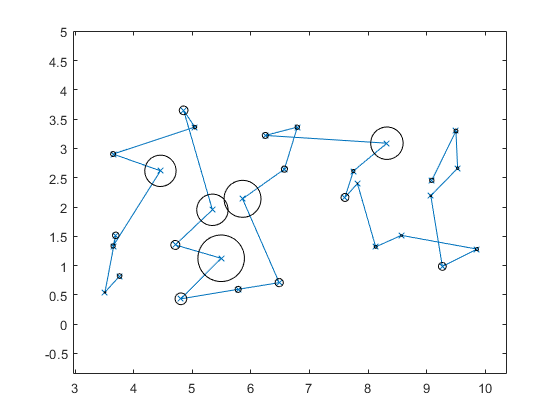

plot(pos(1,:), pos(2,:), '-x'); hold on
for i = 1:width(pos)
    plot_circle(pos(1,i), pos(2,i), 1e-2*multilateration_err_cm(i));
end
hold off
axis equal padded

1e2*std(pos(3,:))

ans = 6.1599

## Write list of XYZ positions to CSV file

csv_mat = [pos(1:3,:)' multilateration_err_cm*1e-2]

csv_mat =     9.0889    2.4557    0.0335    0.0369
    9.5014    3.2987   -0.0004    0.0328
    9.5300    2.6640   -0.0830    0.0220
    9.0725    2.1917   -0.0294    0.0152
    9.2692    0.9860   -0.1194    0.0664
    9.8601    1.2822   -0.0365    0.0281
    8.5703    1.5165   -0.0195    0.0165
    8.1312    1.3202    0.0526    0.0259
    7.8192    2.4015    0.0344    0.0091
    7.6059    2.1635   -0.0076    0.0677


filename = "xyz_camera_cal_uwb_" + datestr(datetime('now'), 'yyyy-mm-dd_HH-MM-SS') + ".csv"

filename = "xyz_camera_cal_uwb_2021-09-20_09-56-55.csv"

writematrix(csv_mat, filename)

function [anchor_names, anchor_locs] = anchor_info(msgs)
% Find the 4 anchors
for i = 1:length(msgs)
    line = msgs{i}.Data;
    line_sp = split(line, ',');
    if line_sp{2} == '4' % Got 4 readings this line
        anchor_names = string([line_sp{4}; line_sp{10}; line_sp{16}; line_sp{22}]);
        line_sp = str2double(line_sp);
        anchor_locs = [line_sp(5) line_sp(11) line_sp(17) line_sp(23)
                       line_sp(6) line_sp(12) line_sp(18) line_sp(24)
                       line_sp(7) line_sp(13) line_sp(19) line_sp(25)];
        break
    end
end
end

function dist_mat = get_distances(msgs, anchors)
dist_mat = NaN(length(msgs), 4);
for i = 1:length(msgs)
        line = msgs{i}.Data;
        if line == ""
            continue
        end
        data = split(line, ',');
        % Anchor labels are at 4,10,16,22
        % Anchor distances are at 8, 14, 20, 26
        N_anch_i = str2double(data{2});
        
        if N_anch_i >= 1
            dist_mat(i, anchors == data{4}) = str2double(data{8});
        end
        if N_anch_i >= 2
            dist_mat(i, anchors == data{10}) = str2double(data{14});
        end
        if N_anch_i >= 3
            dist_mat(i, anchors == data{16}) = str2double(data{20});
        end
        if N_anch_i == 4
            dist_mat(i, anchors == data{22}) = str2double(data{26});
        end
end
end

function h = plot_circle(x,y,r)
d = r*2;
px = x-r;
py = y-r;
h = rectangle('Position',[px py d d],'Curvature',[1,1]);
end